# **Session 2: Building your own data pipeline with DataJoint**

In the session 1, we have introduced important methods to interact with existing data pipeline. In this session we will further introduce how to generate pipelines on your own and ingest data into it.

We will learn:

1. learn what a data pipeline is

2. start designing our first data pipeline based on experiment requirements

3. create the data pipeline in DataJoint

4. insert some data into the pipeline

# So... What is a data pipeline?

If you visit the [documentation for DataJoint](https://docs.datajoint.io/introduction/Data-pipelines.html), we define a data pipeline as follows:

> A data pipeline is a sequence of steps (more generally a directed acyclic graph) with integrated storage at each step. These steps may be thought of as nodes in a graph.

While this is an accurate description, it may not be the most intuitive definition. Put succinctly, a data pipeline is a listing or a "map" of various "things" that you work with in a project, with line connecting things to each other to indicate their dependecies. The "things" in a data pipeline tends to be the *nouns* you find when describing a project. The "things" may include anything from mouse, experimenter, equipment, to experiment session, trial, two-photon scans, electric activities, to receptive fields, neuronal spikes, to figures for a publication! A data pipeline gives you a framework to:

1. define these "things" as tables in which you can store the information about them

2. define the relationships (in particular the dependencies) between the "things"

A data pipeline can then serve as a map that describes everything that goes on in your experiment, capturing what is collected, what is processed, and what is analyzed/computed. A well designed data pipeline not only let's you organize your data well, but can bring out logical clarity to your experiment, and may even bring about new insights by making how everything in your experiment relates together obvious.

Let's go ahead and build together a pipeline from scratch to better understand what a data pipeline is all about.

# **Building our first pipeline: single electrode recording from mouse**

Let's build a pipeline to collect, store and process data and analysis for our hypothetical single electrode recording study in mice. To help us understand the project better, here is a brief description:

- Your lab houses many mice, and each mouse is identified by a unique ID. You also want to keep track of information about each mouse such as their date of birth, and gender.

- As a hard working neuroscientist, you perform experiments every day, sometimes working with more than one mouse in a day! However, on an any given day, a mouse undergoes at most one recording session.

- For each experimental session, you would like to record what mouse you worked with and when you performed the experiment. You would also like to keep track of other helpful information such as the experimental setup you worked on.

- In each experimental session, you record electrical activity from a single neuron. You use recording equipment that produces separate data files for each neuron you recorded.

-  Neuron's activities are recorded as raw traces. Neuron's spikes needs to be detected for further analysis to be performed.

Pipeline design starts by identifying *things* or *entities* in your project. Common entities includes experimental subjects (e.g. mouse), recording sessions, and two-photon scans.

Let's revisit the project description, this time paying special attention to *what *(e.g. nouns) about your experiment. Here I have highlighted some nouns in particular.

-  Your lab houses many **mice**, and each mouse is identified by a unique ID. You also want to keep track of information about each mouse such as their date of birth and gender.

- As a hard working neuroscientist, you perform experiments every day, sometimes working with more than one mouse in a day! However, on an any given day, a mouse undergoes at most one recording session.

- For each **experimental session**, you would like to record what mouse you worked with and when you performed the experiment. You would also like to keep track of other helpful information such as the experimental setup you worked on.

- In each **experimental session**, you record electrical activity from **a single neuron**. You use recording equipment that produces separate data files for each neuron you recorded.

- Neuron's activities are recorded as raw traces. **Neuron's spikes** needs to be detected for further analysis to be performed.

Just by going though the description, we can start to identify *things* or *entities* that we might want to store and represent in our data pipeline:

- mouse

- experimental session

- neuron

- spikes

In DataJoint data pipeline, we represent these* entities* as *tables.* Different *kinds* of entities become distinct tables, and each row of the table is a single example (instance) of the category of entity. 

For example, if we have a `Mouse` table, then each row in the mouse table represents a single mouse!

When constructing such table, we need to figure out what it would take to **uniquely identify** each entry. Let's take the example of the **mouse** and think about what it would take to uniquely identify a mouse.

After some thought, we might conclude that each mouse can be uniquely identified by knowing its **mouse ID** - a unique ID number assigned to each mouse in the lab. The mouse ID is then a column in the table or an **attribute** that can be used to **uniquely identify** each mouse. Such attribute is called the** primary key** of the table.

Once we have successfully identified the primary key of the table, we can now think about what other columns, or **non-primary key attributes** that we would want to include in the table. These are additional **information about each entry in the table that we want to store**.

For the case of mouse, what other information about the mouse you might want to store? Based on the project description, we would probably want to store information such as the mouse's **date of birth** and **gender**.

Now we have an idea on how to represent information about mouse, let's create the table using **DataJoint**!

## Create a schema - house for your tables

Every table lives inside a schema - a logical collection of one or more tables in your pipeline. Your final pipeline may consists of many tables spread across one or more schemas. Let's go ahead and create the first schema to house our table.

We create the schema using `dj.createSchema` function. For this workshop, you are given the database privilege to create any schema **starting with your username followed by a `_` character**. So if your username is `john`, you can make any schema starting with `john_`, such as `john_tutorial`.

% Enter your code, create your own schema here
dj.createSchema

database already exists
Please select a package folder. Opening UI...


Let's create a schema called `tutorial`, prefixed by `username_`. Then create a local package `+tutorial` and link the package to the schema.

Now that we have a schema to place our table into, let's go ahead and define our first table!

## Creating your first table

In DataJoint, you define each table as a class, and provide the table definition (e.g. attribute definitions) as a doc string. The class will inherit from the `dj.Manual` class provided by DataJoint (more on this later). In the MATLAB version of DataJoint, we can create the class by calling the function `dj.new`.

% Enter your code, create your first table!
dj.new

Then we select the type of table we would like to create, in this case, the manual table (M). Then a file callled 'Mouse.m' will automatically be created in the package we created in the last step. Let's edit that file to define the table and create the class.

edit tutorial.Mouse

Let's take a look at our brand new table.

tutorial.Mouse

ans = Object tutorial.Mouse


<SQL>
CREATE TABLE `shans_tutorial`.`mouse` (
`mouse_id` int NOT NULL COMMENT "",
`dob` date                        NOT NULL COMMENT "date of birth",
`sex` enum('M', 'F', 'unknown') NOT NULL COMMENT "sex of the anmial",
PRIMARY KEY (`mouse_id`)
) ENGINE = InnoDB, COMMENT "Experimental mouse"
</SQL>

 :: Experimental mouse ::

0 tuples (2.51 s)


The table was successfully defined, but without any content, the table is not too interesting. Let's go ahead and insert some **mouse** into the table, one at a time using the `insert` method.

Let's insert a mouse with the following information:

- mouse_id: 0

- date of birth: 2018-12-25

- sex: male

% Enter the code to insert a mouse
data = {0, '2018-12-25', 'M'}

data = 1×3 cell array
    {[0]}    {'2018-12-25'}    {'M'}


% insert the data
insert(tutorial.Mouse, data)

Now let's check the table contents:

tutorial.Mouse

ans = Object tutorial.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

       0        '2018-12-25'    'M'

1 tuples (0.182 s)


We can also insert as a struct:

data = struct('mouse_id', 3, 'dob', '2018-07-04', 'sex', 'F');
insert(tutorial.Mouse, data)

tutorial.Mouse

ans = Object tutorial.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

       0        '2018-12-25'    'M'
       3        '2018-07-04'    'F'

2 tuples (0.0593 s)


We can also insert mutiple mice together using the `insert` method, passing in a cell array:

data = {
    4 '2017-08-23' 'F'
    5 '2018-08-25' 'F'
    6 '2018-03-19' 'M'
    }

data = 3×3 cell array
    {[4]}    {'2017-08-23'}    {'F'}
    {[5]}    {'2018-08-25'}    {'F'}
    {[6]}    {'2018-03-19'}    {'M'}


% now insert them all at once
insert(tutorial.Mouse, data)

tutorial.Mouse

ans = Object tutorial.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob         sex
    ________    ____________    ___

       0        '2018-12-25'    'M'
       3        '2018-07-04'    'F'
       4        '2017-08-23'    'F'
       5        '2018-08-25'    'F'
       6        '2018-03-19'    'M'

5 tuples (0.0447 s)


Of course, we can also insert a structure array:

data = [
    struct('mouse_id', 7, 'dob', '2018-07-23', 'sex', 'F')
    struct('mouse_id', 8, 'dob', '2018-09-05', 'sex', 'M')
    struct('mouse_id', 9, 'dob', '2018-07-23', 'sex', 'unknown')
    ]

data = 3×1 struct array with fields:
    mouse_id
    dob
    sex


% now insert them all at once
inserti(tutorial.Mouse, data)

tutorial.Mouse

ans = Object tutorial.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob            sex   
    ________    ____________    _________

       0        '2018-12-25'    'M'      
       3        '2018-07-04'    'F'      
       4        '2017-08-23'    'F'      
       5        '2018-08-25'    'F'      
       6        '2018-03-19'    'M'      
       7        '2018-07-23'    'F'      
       8        '2018-09-05'    'M'      
       9        '2018-07-23'    'unknown'

8 tuples (0.0476 s)


## Data integrity

DataJoint checks for data integrity, and ensures that you don't insert a duplicate by mistake. Let's try inserting another mouse with `mouse_id: 0` and see what happens!

data = {1, '2019-01-05', 'M'}

data = 1×3 cell array
    {[1]}    {'2019-01-05'}    {'M'}


insert(tutorial.Mouse, data)

% insert more mice


# Working with tables with dependencies

Congratulations! We have successfully created your first table. We are now ready to tackle and include other **entities** in the project into our data pipeline. 

Let's now take a look at representing an **experimental session**.

As with mouse, we should think about **what information (i.e. attributes) is needed to uniquely identify an experimental session**. Here is the relevant section of the project description:

- As a hard working neuroscientist, you perform experiments every day, sometimes working with **more than one mouse in a day**! However, on an any given day, **a mouse undergoes at most one recording session**.

- For each experimental session, you would like to record **what mouse you worked with** and **when you performed the experiment**. You would also like to keep track of other helpful information such as the **experimental setup** you worked on.

Based on the above, it appears that you need to know:

- the date of the session

- the mouse you recorded from in that session

to uniquely identify a single experimental session.

Thus we will need both **mouse** and a new attribute **session_date** to uniquely identify a single session. 

Remember that a **mouse** is already uniquely identified by its primary key - **mouse_id**. In DataJoint, you can declare that **session** depends on the mouse, and DataJoint will automatically include the mouse's primary key (`mouse_id`) as part of the session's primary key, along side any additional attribute(s) you specificy.

Primary keys:

- mouse_id

- session_date

Additional Attributes:

- experiment_setup

- experimenter

dj.new

Declare the class to create the table:

tutorial.Session

You can actually generate the entity relationship diagram (ERD) on the fly by calling `erd` with the schema object

erd tutorial

/Users/shanshen/Dropbox/Vathes/princeton/pipelines/main_pipeline/schemas_matlab/tutorials/201910/+tutorial/Session.m already exists


Let's try inserting a few sessions manually.

data = struct( ...

ans = Object tutorial.Session


<SQL>
CREATE TABLE `shans_tutorial`.`session` (
`mouse_id` int NOT NULL COMMENT "",
CONSTRAINT `qKYwdrs0` FOREIGN KEY (`mouse_id`) REFERENCES `shans_tutorial`.`mouse` (`mouse_id`) ON UPDATE CASCADE ON DELETE RESTRICT,
`session_date` date NOT NULL COMMENT "",
`experiment_setup` int   NOT NULL COMMENT "set up number",
`experimenter` varchar(50) NOT NULL COMMENT "name of experimenter",
PRIMARY KEY (`mouse_id`,`session_date`)
) ENGINE = InnoDB, COMMENT "Experimental Session"
</SQL>

 :: Experimental Session ::

0 tuples (31.9 s)


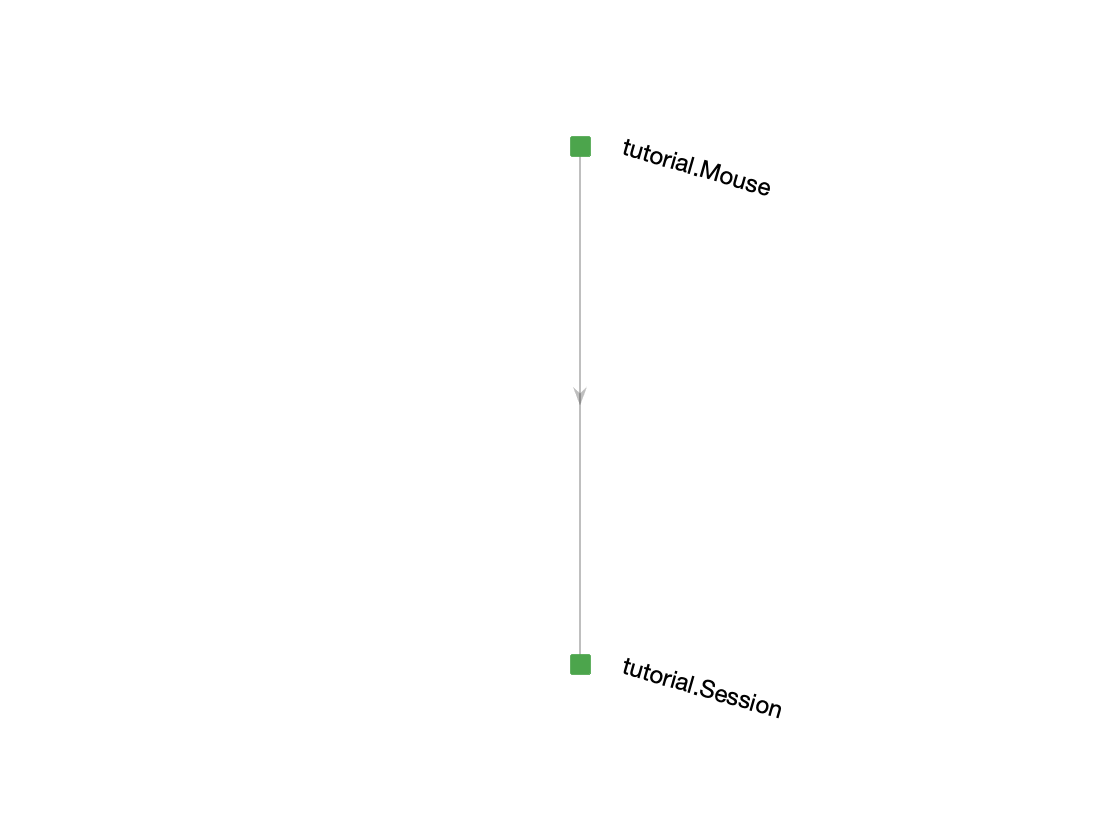

    'mouse_id', 0, ...
    'session_date', '2019-02-01', ...
    'experiment_setup', 0, ...

    'experimenter', 'Shan Shen'...
    )
inserti(tutorial.Session, data)
tutorial.Session

data = struct with fields:
            mouse_id: 0
        session_date: '2019-02-01'
    experiment_setup: 0
        experimenter: 'Shan Shen'


Let's insert another session for `mouse_id = 0` but on a different date.

data = struct( ...
    'mouse_id', 0, ...

ans = Object tutorial.Session

 :: Experimental Session ::

    MOUSE_ID    SESSION_DATE    experiment_setup    experimenter
    ________    ____________    ________________    ____________

       0        '2019-02-01'           0            'Shan Shen' 

1 tuples (0.0947 s)


    'session_date', '2019-02-11', ...
    'experiment_setup', 0, ...
    'experimenter', 'Shan Shen'...
    )
insert(tutorial.Session, data)

data = struct with fields:
            mouse_id: 0
        session_date: '2019-02-11'
    experiment_setup: 0
        experimenter: 'Shan Shen'


tutorial.Session

And another session done on the same date but on a different mouse.

data = struct( ...

ans = Object tutorial.Session

 :: Experimental Session ::

    MOUSE_ID    SESSION_DATE    experiment_setup    experimenter
    ________    ____________    ________________    ____________

       0        '2019-02-01'           0            'Shan Shen' 
       0        '2019-02-11'           0            'Shan Shen' 

2 tuples (6.93 s)


    'mouse_id', 3, ...
    'session_date', '2019-02-13', ...
    'experiment_setup', 100, ...
    'experimenter', 'Dimitri Yatsenko'...
    )

insert(tutorial.Session, data)
tutorial.Session

data = struct with fields:
            mouse_id: 3
        session_date: '2019-02-13'
    experiment_setup: 100
        experimenter: 'Dimitri Yatsenko'


What happens if we try to insert a session for a mouse that doesn't exist?

bad_data = struct( ...
    'mouse_id', 9999, ... % this mouse doesn't exist!

ans = Object tutorial.Session

 :: Experimental Session ::

    MOUSE_ID    SESSION_DATE    experiment_setup       experimenter   
    ________    ____________    ________________    __________________

       0        '2019-02-01'            0           'Shan Shen'       
       3        '2019-02-13'          100           'Dimitri Yatsenko'

2 tuples (0.0473 s)


    'session_date', '2019-02-12', ...
    'experiment_setup', 0, ...
    'experimenter', 'Shan Shen' ...
    )
insert(tutorial.Session, bad_data)

bad_data = struct with fields:
            mouse_id: 9999
        session_date: '2019-02-12'
    experiment_setup: 0
        experimenter: 'Shan Shen'


## Deleting entries

Now we have a good idea on how to restrict table entries, this is a good time to introduce how to **delete** entries from a table.

To delete a specific entry, you restrict the table down to the target entry, for example **mouse_id = 8**, and call `del` method.

% Enter your code here
del(tutorial.Mouse & 'mouse_id = 8')


ABOUT TO DELETE:
       1 tuples from `shans_tutorial`.`mouse` (manual)

Deleting from tutorial.Mouse
committed


tutorial.Mouse

ans = Object tutorial.Mouse

 :: Experimental mouse ::

    MOUSE_ID        dob            sex   
    ________    ____________    _________

       0        '2018-12-25'    'M'      
       3        '2018-07-04'    'F'      
       4        '2017-08-23'    'F'      
       5        '2018-08-25'    'F'      
       6        '2018-03-19'    'M'      
       7        '2018-07-23'    'F'      
       9        '2018-07-23'    'unknown'

7 tuples (0.0801 s)


Calling `del` method on an *unrestricted* table will attempt to delete the whole table!

del(tutorial.Mouse)


ABOUT TO DELETE:
       7 tuples from `shans_tutorial`.`mouse` (manual)
       2 tuples from `shans_tutorial`.`session` (manual)

Deleting from tutorial.Session
Deleting from tutorial.Mouse
committed


Notice that when you try to delete all `Mouse`, `del` also warned that `Session` entries will get deleted! 

DataJoint understands and keeps track of dependencies such that **no dependent entries will be left orphaned**. The `del` operations automatically **cascades down** the dependency to ensure data integrity. We will revisit this point in the next session.

Congratulations! You have successfully created your first DatJoint pipeline, using dependencies to establish the link between the tables.

# Working with automated computations: Imported and Computed tables

Now we are going to continue working with the pipeline for the mouse electrophysiology example. 

We will learn to:

- import neuron activity data from data files into an `Imported` table

- compute various statistics for each neuron by defining a `Computed` table

- define a `Lookup` table to store parameters for computation

- define another `Computed` table to perform spike detection and store the detected spikes

- automatically trigger computations for all missing entries with `populate`

`We first insert some entries in the previous table`

mouse_data = {
    0 '2018-03-01' 'M'
    1 '2017-11-19' 'M'
    2 '2017-11-20' 'unknown'
    5 '2017-12-25' 'F'
    10 '2018-01-01' 'F'
    11 '2018-01-03' 'F'
    100 '2018-05-12' 'F'
    };


session_data = {
    0 '2018-05-15' 0 'Shan Shen'
    0 '2018-05-19' 0 'Shan Shen'
    5 '2018-01-05' 1 'Dimitri Yatsenko'
    100 '2018-05-25' 100 'Edgar Y. Walker' 
    };

inserti(tutorial.Mouse, mouse_data)
inserti(tutorial.Session, session_data)

This script also fills each table with data to make sure we are all on the same page.

# Importing data from data files

Recall from the project description

- In each experimental session, you record electrical activity from a single neuron. You use recording equipment that produces separate data files for each neuron you recorded.

Our recording equipment produces a data file for each neuron recorded. Since we record from one neuron per session, there should be one data file for each session.

In the `data` directory, you will find `.mat` files with names like `data_100_2018-05-25.mat`.

As you might have guessed, these are the data for the recording sessions in the `Session` table, and each file are named according to the `mouse_id` and `session_date` - the attributes of the primary keys - in the format `data_{mouse_id}_{session_date}.mat`.

So `data_100_2018-05-25.mat` is the data for session identified by `mouse_id = 100` and `session_date = "2018-05-25"`.

## Looking at the data

Let's take a quick peek at the data file content.

First, let's pick a session to load the data for. To do this we are going to first fetch all the **primary key attributes** of `Session` as a structure array. We make use of the  `fetch` to achieve this.

keys = fetch(tutorial.Session)

Let's take the first key, and generate the file name that corresponds to this session. Remember the `data_{mouse_id}_{session_date}.mat` filename convetion!

key = keys(1);
filename = sprintf('data/data_%d_%s.mat', key.mouse_id, key.session_date)

Let's take a look at its contents

loaded_data = load(filename);

keys = 4×1 struct array with fields:
    mouse_id
    session_date


data = loaded_data.data

And check the size of the data

size(data)

This vector represents a (simulated) recording of raw arbituary electric activity from a single neuron over 1000 time bins.

figure; plot(data)

filename = 'data/data_0_2018-05-15.mat'

## Defining the table for recorded neurons

We now would like to have all these recorded `Neuron` represented and stored in our data pipeline.

Since we only record a single neuron from each session, a `Neuron` can be uniquely identified by knowing the `Session` it was recorded in. For each `Neuron`, we want to store the neural **activity** found in the data file.

dj.new

Let's declare this table:

tutorial.Neuron

data =     0.3579    0.4475    0.1964    0.3911    0.1767    0.3801    0.0936    0.0111    0.1145    0.1659    0.1021    0.1150    0.2181    0.1341    0.0775    0.0920   -0.0076    1.1281    0.9487    0.7778    0.5468    0.3919    0.2195    0.3920    0.3177    0.2979    0.1856    0.3042    0.0876   -0.0176    0.1437   -0.1283   -0.0438    0.1574    0.1702    0.8986    0.9369    1.6742    2.4816    1.8974    1.4575    1.3214    1.0535    1.8850    1.5332    1.3457    1.9392    1.5884    1.2607    1.2197


Let's check the status of our data pipeline.

erd tutorial

ans =            1        1000


We defined `activity` as a `longblob` so that it can store a vector holding the electric activity over time. This vector will be imported from the file corresponding to each neuron.

Note that our `Neuron` class inherits from `dj.Imported` instaed of `dj.Manual` like others. This is because **this table's content will depend on data imported from an external file**. The `Manual` vs `Imported` are said to specify the **tier of the table**.

## DataJoint table tiers

In DataJoint, the tier of the table indicates **the nature of the data and the data source for the table**. So far we have encountered two table tiers: `Manual` and `Imported`, and we will encounter the two other major tiers in this session. 

DataJoint tables in `Manual` tier, or simply **Manual tables** indicate that its contents are **manually** entered by either experimenters or a recording system, and its content **do not depend on external data files or other tables**. This is the most basic table type you will encounter, especially as the tables at the beggining of the pipeline. In the ERD, `Manual` tables are depicted by green squares.

On the other hand, **Imported tables** are understood to pull data (or *import* data) from external data files, and come equipped with functionalities to perform this importing process automatically, as we will see shortly! In the ERD, `Imported` tables are depicted by blue ellipses.

## Importing data into the `Imported` table

Rather than filling out the content of the table manually using the `insert` methods, we are going to make use of the `makeTuples` and `populate` logic that comes with `Imported` tables to automatically figure out what needs to be imported and perform the import!

## `makeTuples` and `populate` methods

Let us keep the `makeTuples` function empty and try to call the function.

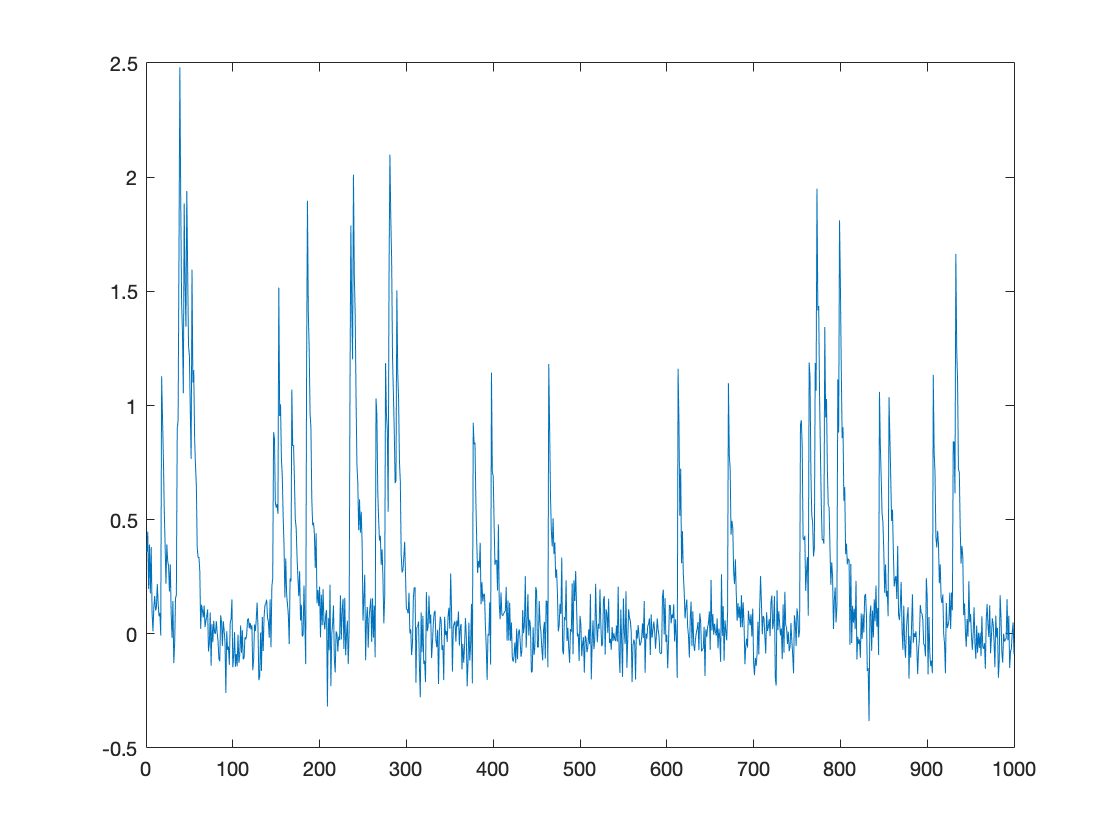

% call the `populate` function
populate(tutorial.Neuron)

When you call `populate` on an `Imported` table, this triggers DataJoint to look up all tables that the `Imported` table depends on.

For **every unique combination of entries in the depended or "parent" tables**, DataJoint calls `makeTuples` function, passing in the primary key of the parent(s).

Because `Neuron` depends on `Session`, `Neuron`'s `makeTuples` method was called for each entry of `Session`

tutorial.Session

Package tutorial is missing. Calling dj.createSchema...


Note that `makeTuples` only receives the *primary key attributes* of `Session` (`mouse_id` and `session_date`) but not the other attributes.

What will happen if we call the `populate` again?

populate(tutorial.Neuron)

Undefined variable "tutorial" or class "tutorial.Neuron".

That's right - nothing! This makes sense, because we have imported `Neuron` for all entries in `Session` and nothing is left to be imported.

Now what happens if we insert a new entry into `Session`?

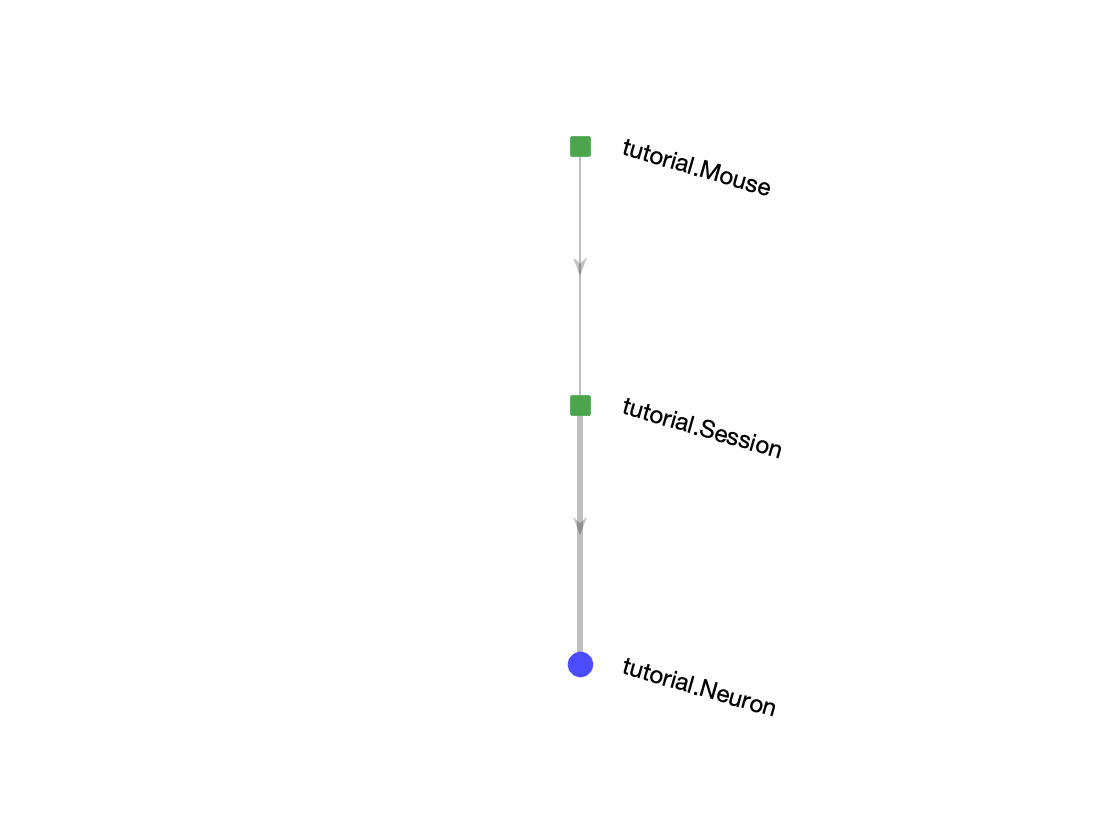

insert(tutorial.Session, {100 "2018-06-01" 1 "Jacob Reimer"})

We can find all `Session` without corresponding `Neuron` entry with the** negative restriction operator** `-`

% select all Session entries *without* a corresponding entry in Neuron
tutorial.Session - tutorial.Neuron


**tutorial.Neuron: Found 4 unpopulated keys

Populating tutorial.Neuron for:
        mouse_id: 0
    session_date: '2018-05-15'

Populating tutorial.Neuron for:
        mouse_id: 0
    session_date: '2018-05-19'

Populating tutorial.Neuron for:
        mouse_id: 5
    session_date: '2018-01-05'

Populating tutorial.Neuron for:
        mouse_id: 100
    session_date: '2018-05-25'



populate(tutorial.Neuron)

ans = Object tutorial.Session

 :: Experimental Session ::

    MOUSE_ID    SESSION_DATE    experiment_setup       experimenter   
    ________    ____________    ________________    __________________

        0       '2018-05-15'            0           'Shan Shen'       
        0       '2018-05-19'            0           'Shan Shen'       
        5       '2018-01-05'            1           'Dimitri Yatsenko'
      100       '2018-05-25'          100           'Edgar Y. Walker' 

4 tuples (1 s)


tutorial.Neuron

tutorial.Neuron: Nothing to populate


# Computations in data pipeline

Now we have successfully imported all data we have into our pipeline, it's time for us to start analyzing them! 

When you perform computations in the DataJoint data pipeline, you focus and design tables in terms of **what** is it that you are computing rather than the **how**. You should think in terms of the "things" that you are computing!

Now, let's say that we want to compute the satististics, such as mean, standard deviation, and maximum value of each of our neuron's activity traces. Hence we want to compute the neuron's **activity statistics** for each neuron!

So the new "thing" or entity here is `ActivityStatistics`, where each entry corresponds to the statistics of a single `Neuron`. Let's start designing the table, paying special attention to the dependencies.

**Statistics of neuron activities**

Before we create the table to store the statistics, let's think about how we might go about computing interesting statistics for a single neuron.

Let's start by fetching one neuron to work with.

keys = fetch(tutorial.Neuron);

% pick one key
key = keys(1)

tutorial.Neuron & key

ans = Object tutorial.Session

 :: Experimental Session ::

    MOUSE_ID    SESSION_DATE    experiment_setup     experimenter 
    ________    ____________    ________________    ______________

      100       '2018-06-01'           1            'Jacob Reimer'

1 tuples (1 s)


Let's then grab the `activity` data as a vector. As discussed in the last session, we can fetch it!

activity = fetch1(tutorial.Neuron & key, 'activity')


**tutorial.Neuron: Found 1 unpopulated keys

Populating tutorial.Neuron for:
        mouse_id: 100
    session_date: '2018-06-01'



Now we can compute some statistics.

% mean activity


% standard deviation of the activity


% maximum of the activity


This gives us a good idea on how to:

1. fetch the activity of a neuron knowing its primary key, and

2. compute interesting statistics

Armed with this knowledge, let's go ahead and define the table for 

with primary keys:

- primary keys in table Neuron

and additional attributes:

- mean

- stdev

- max

**Defining **`ActivityStatistics`** table**

Let's go ahead and work out the definition of the table.

dj.new

Let's go ahead to populate the table.

populate(tutorial.ActivityStatistics)

tutorial.ActivityStatistics

Now you have computed the activity statistics for each neuron!

# Spike detection

Now, let's go ahead and tackle a more challenging computation. While having raw neural traces in itself can be quite interesting, nothing is as exciting as spikes! Let's take a look at the neurons activities and plot them.

% get all keys


% fetch all activities - returned as a cell array


figure; 
for i = 1:length(activities)
    subplot(length(activities),1, i)
    activity = activities(i);
    plot(activity{:})
    xlabel('Time')
    ylabel('Activity')
end

Now let's focus on one trace instead.

figure;
activity = fetch1(tutorial.Neuron & keys(1), 'activity');
plot(activity); xlabel('Time'); ylabel('Activity'); xlim([0, 300])

Perhaps we can use threshold to detect when a spike occurs.Threshold of 0.5 might be a good start.

threshold = 0.5;

% find activity above threshold
above_thrs = activity > threshold;   

figure; hold on
plot(activity)
plot(above_thrs)
xlabel('Time')
xlim([0, 300])

We want to find out **when** it crossed the threshold. That is, find time bins where `above_thrs` goes from 0 (`False`) to 1 (`True`).

rising = diff(above_thrs) > 0;  % find rising edge of crossing threshold
spikes = [0, rising];   % prepend 0 to account for shortening due to diff

figure; hold on
plot(activity)
plot(above_thrs)
plot(find(spikes>0), 1,  'ro'); % plot only spike points
xlabel('Time')
xlim([0, 300])

Finally, let's also compute the spike counts.

count = sum(spikes)

Here is our complete spike detection algorithm:

% Enter your code here - try different values of threshold!
%threshold = 

% find activity above threshold
above_thrs = activity > threshold;
rising = diff(above_thrs) > 0;  % find rising edge of crossing threshold
spikes = [0, rising];   % prepend 0 to account for shortening due to diff
count = sum(spikes)    % compute totoal spk counts

figure; hold on
plot(activity)
plot(above_thrs)
plot(find(spikes>0), 1,  'ro'); % plot only spike points
xlabel('Time')
xlim([0, 300])

 Now notice that the exact spikes you detect depend on the value of the `threshold`. Therefore, the `threshold` is a parameter for our spike detection computation. Rather than fixing the value of the threshold, we might want to try different values and see what works well.

In other words, you want to compute `Spikes` for a **combination** of `Neuron`'s and different `threshold` values. To do this while still taking advantage of the `makeTuples` and `populate` logic, you would want to define a table to house parameters for spike detection in a `Lookup` table!

## Parameter `Lookup` table

Let's define `SpikeDetectionParam` table to hold different parameter configuration for our spike detection algorithm. We are going to define this table as a `Lookup` table, rather than a `Manual` table. By now, you know that `Lookup` must be yet another **table tier** in DataJoint. `Lookup` tables are depicted by a **gray star** in the ERD.

This tier indicates that the table will contain information:

- that will be referenced by other tables

- that doesn't change much - usually contains a few pre-known entries

dj.new

tutorial.SpikeDetectionParam

figure; erd tutorial

**Defining **`Spikes`** table**

dj.new

The implementation of the spike detection is pretty much what we had above, except that we now fetch the value of `threshold` from the `SpikeDetectionParam` table.

Looking at the `Spikes` table, we see that it indeed inherits the primary key attributes from **both Neuron (`mouse_id`, `session_date`) and SpikeDetectionParam (`sdp_id`)**

tutorial.Spikes

**Populating **`Spikes`** table**

We are now ready to populate! When we call `populate` on `Spikes`, DataJoint will automatically call `make` on **every valid combination of the parent tables - Neuron and SpikeDetectionParam**.

% Enter your code, populate the Spike table


Why there is nothing to populate? Looking at `SpikeDetectionParam` reveals the issue:

tutorial.SpikeDetectionParam

That's right! We have not added a detection parameter set yet. Let's go ahead and add one.

insert(tutorial.SpikeDetectionParam, {0, 0.5})
tutorial.SpikeDetectionParam

% populate the Spike table for real!
populate(tutorial.Spikes)

Check the table

tutorial.Spikes

**Trying out other parameter values**

insert(tutorial.SpikeDetectionParam, {1, 0.9})
tutorial.SpikeDetectionParam

Let's see how different thresholds affect the results.

populate(tutorial.Spikes)

tutorial.Spikes

You can see that the results of spike detection under different parameter settings can live happily next to each other, without any confusion as to what is what.

Let's insert a couple more entries into `SpikeDetectionParam` 

insert(tutorial.SpikeDetectionParam, {
2, 0.8
3, 0.6
4, 0.3
})

tutorial.SpikeDetectionParam

What if I only want to populate with `sdp_id=3`?

There are two approaches. 

First approach, restrict when calling the `populate` method

% Enter your code here, restrict the populate


Second approach, restrict in the class `tutorial.Spikes` with a property called `popRel`

edit tutorial.Spikes

populate(tutorial.Spikes)

The first approach is applicable to quickly populating a sebset of the entries, while the second is suitable for more systematic restrictions.

## Deleting entries "upstream"

Now let's say that we decided that we don't like the first spike threshold of `0.5`. While there is really nothing wrong keeping those results around, you might decide that you'd rather delete all computations performed with that threshold to keep your tables clean.

While you can restrict `Spikes` table to the specific parameter id (i.e. `sdp_id = 0`) and delete the entries:

% Enter your code here to delete all entries with sdp_id = 0


We can also simply delete the unwanted paramter from the `SpikeDetectionParam` table, and let DataJoint cascade the deletion:

del(tutorial.SpikeDetectionParam  & 'sdp_id = 0')

tutorial.Spikes

# Summary

Congratulations! You have successfully extended your pipeline with a table to represent recorded data (`Neuron` as `Imported` table), tables that performs and represents computation results (`ActivityStatistics` and `Spikes` as `Computed` tables) and a table to hold computation parameters (`SpikeDetectionParam` as `Lookup` table).

erd tutorial

Our pipeline is still fairly simple but completely capable of handling analysis!

In the next session, we are going to revisit some of the **common design patterns** that were used when designing our pipeline. We will also tackle some more query challenges to horn in our DataJoint querying skills.